# Focal surface

For an eye with a given level of accommodation, we can obtain for each point of the visual field the internal focal point in the eye. The surface defined by these points can be compared to the retinal surface. 

For this demonstration, we will create an eye accommodated to a distance of 1 meter, with stigmatic but centered optical elements.

eye = modelEyeParameters('accommodation',1,'kvals',[43.3990, 44.3365 0 0 0]);

Whe we define visual field positions below, we will do so with respect to these reference points:

angleReferenceCoord = eye.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eye);
rayOriginDistance = 1000;

Generate and plot the optical system:

opticalSystem = assembleOpticalSystem(eye,'surfaceSetName','mediumToRetina');
plotOpticalSystem('surfaceSet',opticalSystem,'addLighting',true);
hold on

Now loop over visual field positions and plot the focal points, color coded by the distance with which the focal point misses the surface of the retina

S = eye.retina.S;
for hh = -40:40
    for vv = -40:40
        iFP = calcInternalFocalPoint(opticalSystem,[hh vv],rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
        fpError = quadric.distancePointEllipsoid(iFP,S);
        color = [1 min([1 fpError]) 0];
        plot3(iFP(1),iFP(2),iFP(3),'.','Color',color)
    end
end

Add the fovea

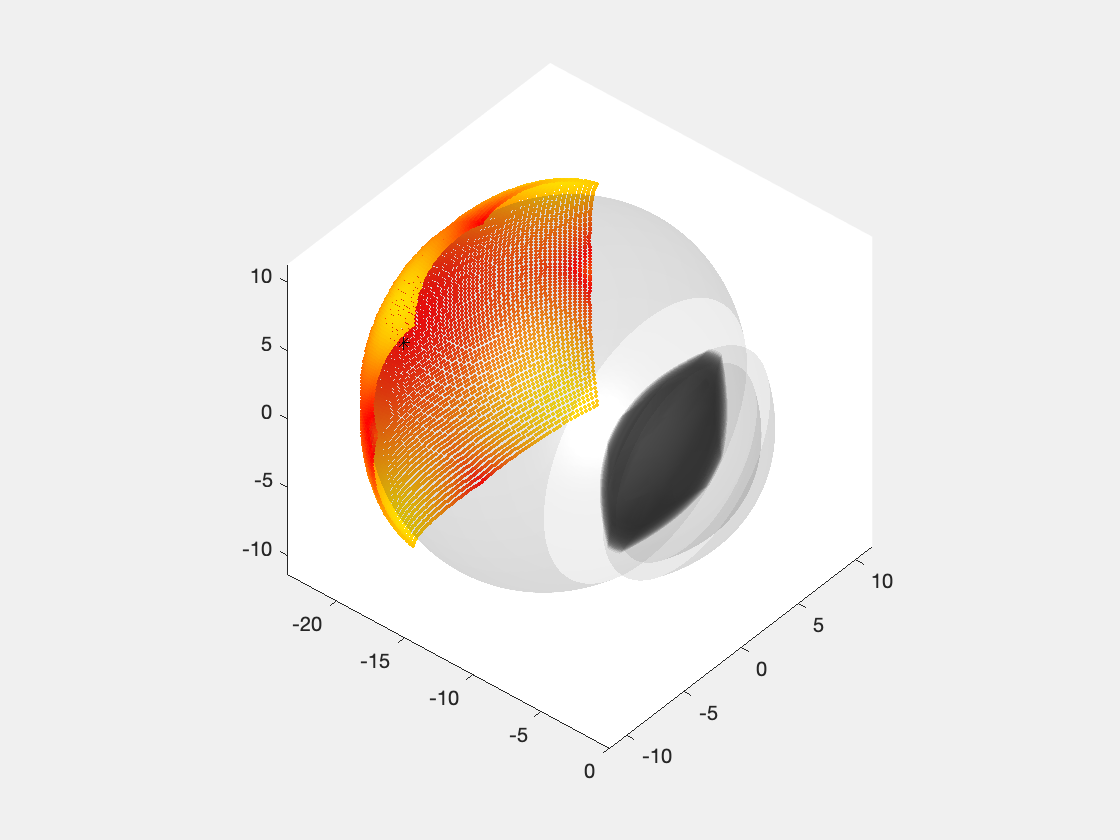

X = eye.landmarks.fovea.coords;
plot3(X(1),X(2),X(3),'*k')